# **youBot dynamic model**

## Robot dynamic model

If we consider the dynamic model of a rigid robot as described in Khalil 2002, Chapter 9, with $\mathit{\mathbf{M}}$ the mass-inertia matrix of the robot, $\mathit{\mathbf{h}}$ the vector regrouping velocities and accelerations related torques, $\tau_r \;\;\textrm{and}\;\tau_e$ respectively the robot control and environment torques.


$$\mathbf{M}(\mathbf{q})\ddot{\mathbf{q}} + \mathbf{h}(\dot{\mathbf{q}}, \mathbf{q}) = \mathbf{\tau}_r + \mathbf{\tau}_{e}$$


If we consider the force ${\mathit{\mathbf{f}}}_e$ that is applied by the environnement on the robot (that is provided by the sensor ${\mathit{\mathbf{f}}}_s$), the Coriolis and Centrifugal torques $\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)$, the viscous matrix ${\mathit{\mathbf{F}}}_v$, the static friction torques ${\mathit{\mathbf{f}}}_s$ and the gravity torque $\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)$, the dynamic equation can be explicited as follow:

 
$$\ddot{\mathit{\mathbf{q}}} ={M\left(\mathit{\mathbf{q}}\right)}^{-1} \left(\tau {\;}_r -{\nu \mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_{r\to e} -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -{\mathit{\mathbf{f}}}_s \left(\dot{\mathit{\mathbf{q}}} \right)-\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)-\tau_0 \right)$$



$${\mathit{\mathbf{f}}}_e ={\mathit{\mathbf{f}}}_{e\to r} =-{\mathit{\mathbf{f}}}_{r\to e} =-{\mathit{\mathbf{f}}}_s$$


with $\nu \;$the transmission efficiency between the environment force and the robot torque, and $\mathit{\mathbf{J}}$the jacobian of the robot.

**TODO: Inverse dynamic model implemented and validated ?**


$$\tau {\;}_r =M\left(\mathit{\mathbf{q}}\right)\ddot{\mathit{\mathbf{q}}} +\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} +\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)+{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -{\mathit{\mathbf{f}}}_s \left(\dot{\mathit{\mathbf{q}}} \right)-{\nu \mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_{e\to r} +\tau_0$$



$${\mathit{\mathbf{f}}}_s \left(\dot{\mathit{\mathbf{q}}} \right)=\left\lbrace \begin{array}{ll}
\;\textrm{sign}\left({\mathit{\mathbf{f}}}_{r\to e} \right)\min \left(\left|{\mathit{\mathbf{f}}}_{r\to e} \right|{,\;\mathit{\mathbf{f}}}_s \right) & \left|\dot{\mathit{\mathbf{q}}} \right|<\epsilon \\
\textrm{sign}\left(\dot{\mathit{\mathbf{q}}} \right){\;\mathit{\mathbf{f}}}_s  & \left|\dot{\mathit{\mathbf{q}}} \right|>\epsilon 
\end{array}\right.$$


% cleaning workspace variables
clear all
clc
addpath('dynamic_sim\')
dt = 1e-3;
% symbolic states
q = sym('q',[3 1],'real');
q'

$$ans = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

dq = sym('dq',[3 1],'real');
dq'

$$ans = \left(\begin{array}{ccc} {\mathrm{dq}}_{1} & {\mathrm{dq}}_{2} & {\mathrm{dq}}_{3} \end{array}\right)$$

fe = sym('fe',[3 1],'real');
fe'

$$ans = \left(\begin{array}{ccc} {\mathrm{fe}}_{1} & {\mathrm{fe}}_{2} & {\mathrm{fe}}_{3} \end{array}\right)$$

Fv = diag([0.5,0.37,0.7]);                 % viscous matrix
J = J0E_3DOF(q(1),q(2),q(3));              % jacobian matrix
iM = iM_3DOF(q(2),q(3));                   % inverse mass-inertia matrix
Cor = C_3DOF(dq(1),dq(2),dq(3),q(2),q(3)); % Coriolis matrix
g = G_3DOF(q(1),q(2),q(3));                % gravity vector
Fs = diag([0.9, 1.3, 0.5]);                % static friction matrix
fs = Fs*sign(dq);                          % static friction torques
nu = diag([0.8554, 0.5780, 0.9997]);       % transmission efficiency
tau0 = [1.0000; 0.6119; 0.8268];           % torque offsets

## **Robot control**

Let's call ${\mathit{\mathbf{C}}}_v$ the joint velocity controler of the youBot drivers. It generates current setpoints, that can be converted to motor torques using the torque constants matrix ${\mathit{\mathbf{T}}}_c$, and then to joint torques with the gear ratios matrix $\mathit{\mathbf{R}}$, the inner current dynamics are neglected since their time response are in tenth of microseconds. Therefore, the torque setpoints are considered to be the actual robot torques:


$$\mathbf{\tau}_r \approx \mathbf{\tau}_d = \mathbf{R} \mathbf{T}_c \mathbf{i}_d  = \mathbf{R} \mathbf{T}_c \mathbf{C}_v \left( \dot{\mathbf{q}}_d - \dot{\mathbf{q}} \right) = \mathbf{R} \mathbf{T}_c  \left( \mathbf{K}_v \left( \dot{\mathbf{q}}_d - \dot{\mathbf{q}} \right) + \mathbf{K}_{vi} \int \left( \dot{\mathbf{q}}_d - \dot{\mathbf{q}} \right) \mathrm{d}t \right)$$


The joint velocity setpoint $\dot{{\mathit{\mathbf{q}}}_d }$ is obtained thanks to the cartesian admittance controler ${\mathit{\mathbf{C}}}_z$. The conversion from the cartesian to the joint space is done using the estimated inverse jacobian (in a known space where it is well defined).


$$\dot{\mathbf{q}}_d = \hat{\mathbf{J}}(\mathbf{q})^{-1} \mathbf{C}_z ( \mathbf{f}_e ) = \hat{\mathbf{J}}(\mathbf{q})^{-1} \left( \mathbf{K}_p \mathbf{f}_e + \mathbf{K}_{i} \int \mathbf{f}_e \,\mathrm{d}t \right)$$


% torque constants and gear ratios
Tc = diag([0.0335;0.0335;0.051]);
R = diag([156;100;71]);
% velocity control gains
Kv = diag([2500;1500;2000]./256)

Kv =     9.7656         0         0
         0    5.8594         0
         0         0    7.8125


Kvi = diag([3000;900;1000]./65536./dt) % the integral action is already included in the gain

Kvi =    45.7764         0         0
         0   13.7329         0
         0         0   15.2588


% admittance control gains
cz = sym('cz',[2 1],'real');
Kp = diag([0, cz(1), 0]) % 0.015 in CASE (2020) paper

$$Kp = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & {\mathrm{cz}}_{1} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Ki = diag([0, cz(2), 0]) % 0.080 in CASE (2020) paper

$$Ki = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & {\mathrm{cz}}_{2} & 0\\ 0 & 0 & 0 \end{array}\right)$$

% inverse Jacobian
iJ = iJ0E_3DOF(q(1),q(2),q(3));

## Linearisation

The dynamic equation is modeled for the cartesian acceleration $\ddot{\mathit{\mathbf{x}}}$ using the differential of the known (Khalil) relation between the joint velocity and the cartesian velocity. $\ddot{\mathit{\mathbf{x}}} =\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)\;\ddot{\mathit{\mathbf{q}}} +\dot{\mathit{\mathbf{J}}} \left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$


$$\ddot{\mathit{\mathbf{x}}} ={J\left(\mathit{\mathbf{q}}\right)M\left(\mathit{\mathbf{q}}\right)}^{-1} \left(\tau {\;}_r +{\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -{\mathit{\mathbf{f}}}_s \left(\dot{\mathit{\mathbf{q}}} \right)-\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)-\tau_0 \right)+\dot{\mathit{\mathbf{J}}} \left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$$


Then we can define a function ${\mathit{\mathbf{f}}}_1 :\mathit{\mathbf{q}}\;,\dot{\mathit{\mathbf{q}}} \;,\;{\mathit{\mathbf{f}}}_e \;,{\mathit{\mathbf{f}}}_e^{\prime } \;,{\mathit{\mathbf{f}}}_e^{\textrm{''}} \to \ddot{\mathit{\mathbf{x}}}$, with ${\mathit{\mathbf{f}}}_e^{\prime } \;,{\mathit{\mathbf{f}}}_e^{\textrm{''}}$ being respectively the integral and the double integral of the force.

We can also define a function $\mathit{\mathbf{f}}:\mathit{\mathbf{q}}\;,\;\dot{\mathit{\mathbf{q}}} \;,\;\;{\mathit{\mathbf{f}}}_e \;,\;{\mathit{\mathbf{f}}}_e^{\prime } \;,\;{\mathit{\mathbf{e}}}_v \to \ddot{\mathit{\mathbf{x}}}$, with the following definitions (to simplify the computation compared to the previous definition):


$${\mathit{\mathbf{e}}}_v =\int \dot{{\mathit{\mathbf{q}}}_d } \;-\dot{\mathit{\mathbf{q}}} \;\;\textrm{dt}$$



$${\mathit{\mathbf{f}}}_e^i =\int {\mathit{\mathbf{f}}}_e \;\;\textrm{dt}$$


% augmented symbolic states
ev = sym('ev',[3 1],'real');
ev'

$$ans = \left(\begin{array}{ccc} {\mathrm{ev}}_{1} & {\mathrm{ev}}_{2} & {\mathrm{ev}}_{3} \end{array}\right)$$

ife = sym('ife',[3 1],'real');
ife'

$$ans = \left(\begin{array}{ccc} {\mathrm{ife}}_{1} & {\mathrm{ife}}_{2} & {\mathrm{ife}}_{3} \end{array}\right)$$

% robot control torques
tau_r = R*Tc*(Kv*(iJ*(Kp*fe + Ki*ife) - dq) + Kvi*ev)

$$tau\_r = \begin{array}{l} \left(\begin{array}{c} \frac{979875\,{\mathrm{ev}}_{1}}{4096}-\frac{13065\,{\mathrm{dq}}_{1}}{256}+\frac{326625\,\sin\left(q_{1}+q_{2}\right)\,\sigma_{1}}{992\,\sin\left(q_{2}\right)}\\ \frac{376875\,{\mathrm{ev}}_{2}}{8192}-\frac{5025\,{\mathrm{dq}}_{2}}{256}-\frac{41875\,\sigma_{1}\,\left(27\,\sin\left(q_{1}+q_{2}\right)+31\,\sin\left(q_{1}\right)\right)}{8928\,\sin\left(q_{2}\right)}\\ \frac{452625\,{\mathrm{ev}}_{3}}{8192}-\frac{3621\,{\mathrm{dq}}_{3}}{128}+\frac{30175\,\sin\left(q_{1}\right)\,\sigma_{1}}{144\,\sin\left(q_{2}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{cz}}_{1}\,{\mathrm{fe}}_{2}+{\mathrm{cz}}_{2}\,{\mathrm{ife}}_{2} \end{array}$$

% robot dynamic model function
f = J*iM*( tau_r + nu*J'*fe - (Fv + Cor)*dq - g - tau0) + dJ0E_3DOF(q(1),q(2),q(3))*dq;

We can now define $\tilde{\ddot{\mathit{\mathbf{x}}} }$ small variations of accelerations, resulting from the linearisation of the function $\mathit{\mathbf{f}}$, with ${\mathit{\mathbf{X}}}_0$ the equilibrium states such that:


$$\tilde{\ddot{\mathit{\mathbf{x}}} } =\delta \mathit{\mathbf{f}}\left(\mathit{\mathbf{q}}\;,\;\dot{\mathit{\mathbf{q}}} \;,\;\;{\mathit{\mathbf{f}}}_e \;,\;{\mathit{\mathbf{f}}}_e^{\prime } \;,\;{\mathit{\mathbf{e}}}_v \right)=\frac{\partial }{\partial \mathit{\mathbf{q}}}\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{\mathit{\mathbf{q}}} +\frac{\partial }{\partial \dot{\mathit{\mathbf{q}}} }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{\dot{\mathit{\mathbf{q}}} } +\frac{\partial }{\partial \dot{{\mathit{\mathbf{f}}}_e } }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{{\mathit{\mathbf{f}}}_e } +\frac{\partial }{\partial {\mathit{\mathbf{f}}}_e^{\prime } }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{{\mathit{\mathbf{e}}}_v } +\frac{\partial }{\partial {\mathit{\mathbf{e}}}_v }\left(\mathit{\mathbf{f}}\right)|_{{\mathit{\mathbf{X}}}_0 } \;\tilde{{\mathit{\mathbf{f}}}_e^{\prime } }$$


% equilibrium values
q0 = [pi/2; 0; -pi/2] - ([1.676; -4.363; 1.497] - [65; -146; 102.5].*pi/180); % DH convention
dq0 = [0;0;0];
fe0 = [0;0;0];
ife0 = [0;0;0];
ev0 = [0;0;0];

*The state representation of the linearised model seems to be more efficient..*

## State space representation

We can define a state representation for the linearisation of the dynamic model. The input of the state system is the force $\;{\mathit{\mathbf{f}}}_e$, and the inner states $\phi$ are the joint variables $\mathit{\mathbf{q}}\;,\;\dot{\mathit{\mathbf{q}}}$ and the augmented states ${\mathit{\mathbf{f}}}_e^{\prime } \;,\;{\mathit{\mathbf{e}}}_v$. 


$$\phi^˙ =\mathit{\mathbf{A}}\phi \;+\textrm{Bu}$$


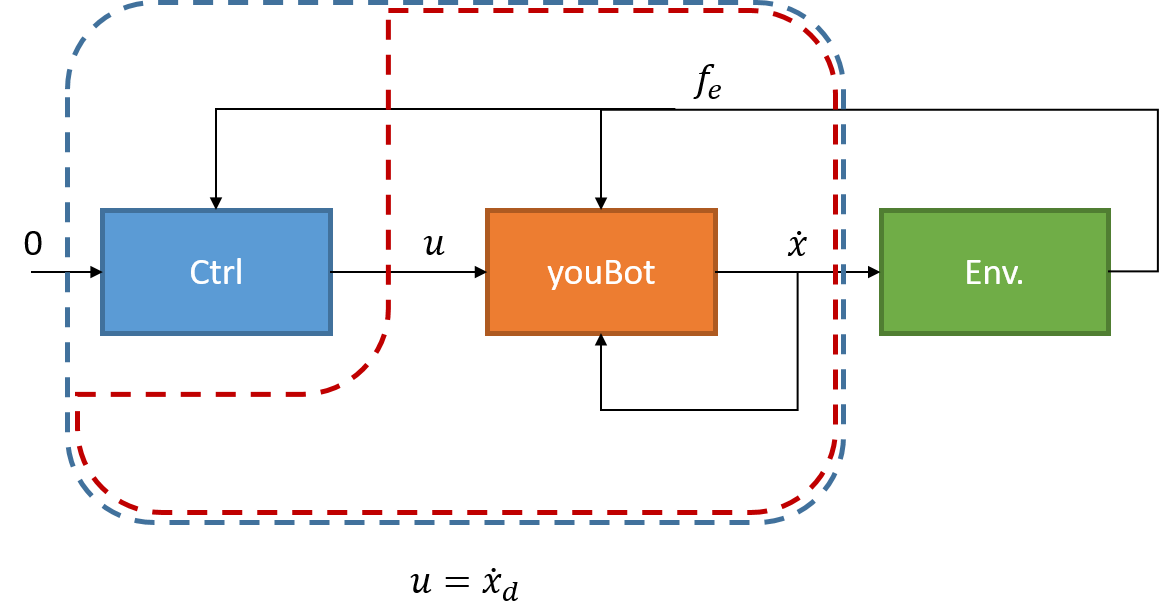

The following equations helps to define the matrices ***A*** and ***B ***for the part of the bloc diagram circle with **dashed blue** lines :

- 
$$\ddot{\mathit{\mathbf{q}}} ={M\left(\mathit{\mathbf{q}}\right)}^{-1} \left({\mathit{\mathbf{K}}}_v \left({\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^{-1} \left({\mathit{\mathbf{K}}}_p {\;\mathit{\mathbf{f}}}_e +{\mathit{\mathbf{K}}}_i \;{\mathit{\mathbf{f}}}_e^{\prime } \right)-\dot{\mathit{\mathbf{q}}} \right)+{\mathit{\mathbf{K}}}_{\textrm{vi}} {\;\mathit{\mathbf{e}}}_v +{\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)-\tau_0 \right)$$


- 
$$\dot{{\mathit{\mathbf{e}}}_v } ={\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^{-1} \left({\mathit{\mathbf{K}}}_p {\;\mathit{\mathbf{f}}}_e +{\mathit{\mathbf{K}}}_i \;{\mathit{\mathbf{f}}}_e^{\prime } \right)-\dot{\mathit{\mathbf{q}}}$$


- 
$$\dot{{\mathit{\mathbf{f}}}_e^{\prime } } ={\mathit{\mathbf{f}}}_e$$


% state
state = [q;dq;ev;ife];
state'

$$ans = \left(\begin{array}{cccccccccccc} q_{1} & q_{2} & q_{3} & {\mathrm{dq}}_{1} & {\mathrm{dq}}_{2} & {\mathrm{dq}}_{3} & {\mathrm{ev}}_{1} & {\mathrm{ev}}_{2} & {\mathrm{ev}}_{3} & {\mathrm{ife}}_{1} & {\mathrm{ife}}_{2} & {\mathrm{ife}}_{3} \end{array}\right)$$

in = fe;
in'

$$ans = \left(\begin{array}{ccc} {\mathrm{fe}}_{1} & {\mathrm{fe}}_{2} & {\mathrm{fe}}_{3} \end{array}\right)$$

% derivatives
ddq = iM*(R*Tc*(Kv*(iJ*(Kp*fe + Ki*ife) - dq) + Kvi*ev) + nu*J'*fe - Fv*dq - Cor*dq - g - tau0); %
dev = iJ*(Kp*fe + Ki*ife) - dq;
% function regrouping the derivative of the state
fss = [dq;ddq;dev;fe]; % phi dot

The linearisation for the state representation can be done using the formula provided in the previous section with the partial derivatives:

% linearisation
A = jacobian(fss,state);
B = jacobian(fss,in);

If we chose to observe only the kinematic behaviour on the z axis, we can define the observation matrix and perturbation as follow:


$$y=\mathit{\mathbf{C}}\phi \;+\mathit{\mathbf{D}}\mathit{\mathbf{u}}$$


Using this relation: $\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$

yss = [0 1 0]*J*dq;
% linearisation
C = jacobian(yss,state);
D = jacobian(yss,in); % zeros

The following equations helps to define the matrices ${\mathit{\mathbf{A}}}_b$ and $B_b$ for the part of the bloc diagram circle with **dashed red** lines, providing a transfer function without the cartesian admittance controller (so the controler can be changed more easily):

- 
$$\ddot{\mathit{\mathbf{q}}} ={M\left(\mathit{\mathbf{q}}\right)}^{-1} \left(\tau_d +{\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)-\tau_0 \right)$$


- 
$$\tau_d ={\textrm{RT}}_c \left({\mathit{\mathbf{K}}}_v \left(\dot{{\mathit{\mathbf{q}}}_d } -\dot{\mathit{\mathbf{q}}} \right)+{\mathit{\mathbf{K}}}_{\textrm{vi}} \int \;\left(\dot{{\mathit{\mathbf{q}}}_d } -\dot{\mathit{\mathbf{q}}} \right)\textrm{dt}\right)$$


- 
$$\dot{{\mathit{\mathbf{q}}}_d } =\hat{\mathit{\mathbf{J}}} {\left(\mathit{\mathbf{q}}\right)}^{-1} \mathit{\mathbf{u}}$$


% states and inputs/ouputs
u = sym('u',[3 1],'real'); % cartesian velocity cmd
u(1) = 0; u(3) = 0; % secondary controls on x and theta are neglected
state_b = [q;dq;ev];
in_b    = [u(2);fe]; % only velocity cmd on z is considered
% derivatives
ddq_b = iM*(R*Tc*(Kv*(iJ*u - dq) + Kvi*ev) + nu*J'*fe - Fv*dq - Cor*dq - g - tau0); %
dev_b = iJ*u - dq;
fss_b = [dq;ddq_b;dev_b];
yss_b = [0 1 0]*J*dq; % output (vz only)
% linearisation
A_b = jacobian(fss_b, state_b);
B_b = jacobian(fss_b, in_b);
C_b = jacobian(yss_b, state_b);
D_b = jacobian(yss_b, in_b); % zeros

Let's consider the matrices ${\mathit{\mathbf{A}}}_{\textrm{youBot}}$ and $B_{\textrm{youBot}}$ for the part of the bloc diagram circle with **dashed red** lines but without the joint velocity controler, such that the considered inputs are $\tau_d$ and ${\mathit{\mathbf{f}}}_e$:

- 
$$\ddot{\mathit{\mathbf{q}}} ={M\left(\mathit{\mathbf{q}}\right)}^{-1} \left(\tau_d +{\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)}^t \;{\mathit{\mathbf{f}}}_e -{\mathit{\mathbf{F}}}_v \;\dot{\mathit{\mathbf{q}}\;} -\mathit{\mathbf{C}}\left(\mathit{\mathbf{q}},\dot{\mathit{\mathbf{q}}} \right)\dot{\mathit{\mathbf{q}}} -\mathit{\mathbf{g}}\left(\mathit{\mathbf{q}}\right)-\tau_0 \right)$$


% states and inputs/ouputs of the youBot alone
u_tau = sym('u_tau',[3 1],'real'); % torque cmd input
state_youBot = [q;dq];
in_youBot    = [u_tau;fe(2)]; % only the force on z is considered
% derivatives
ddq_youBot = iM*(u_tau + nu*J'*[0;fe(2);0] - Fv*dq - Cor*dq - g - tau0); %
fss_youBot = [dq;ddq_youBot];
yss_youBot = dq; % output is joint velocities
% linearisation
A_youBot = jacobian(fss_youBot, state_youBot);
B_youBot = jacobian(fss_youBot, in_youBot);
C_youBot = jacobian(yss_youBot, state_youBot);
D_youBot = jacobian(yss_youBot, in_youBot); % zeros

Linearisation of the jacobian matrices around the equilibrium ${\mathit{\mathbf{q}}}_0$:

- 
$$\dot{{\mathit{\mathbf{q}}}_d } =\hat{\mathit{\mathbf{J}}} {\left(\mathit{\mathbf{q}}\right)}^{-1} \mathit{\mathbf{u}}$$


- 
$$\epsilon_{\dot{q} } =\dot{{\mathit{\mathbf{q}}}_d } -\dot{\mathit{\mathbf{q}}}$$


- 
$$\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{J}}\left(\mathit{\mathbf{q}}\right)\dot{\mathit{\mathbf{q}}}$$


iJ0 = double(subs(iJ, q, q0));
J0 = double(subs(J, q, q0));

The discrete form of the controlers, with sampling period $\delta t$ are considered:

- 
$$C_v \left(z\right)=\frac{\tau_r \left(z\right)}{\epsilon_{\dot{q} } \left(z\right)}={\textrm{RT}}_c \left({\mathit{\mathbf{K}}}_v +\frac{z}{z-1}{\mathit{\mathbf{K}}}_{\textrm{vi}} \right)$$


- 
$$C_z \left(z\right)=\frac{v_d \left(z\right)}{f\left(z\right)}=\left(K+\frac{z}{z-1}K_i \;\delta t\right)$$


z = tf('z', dt);
% joint velocity controller
% Kvi was divided by dt, but in the implemented gain, dt is already considered 
Cv_d = Kv + z/(z-1)*Kvi*dt;
% Cz_d is implemented in the numeric evaluation (next section).

## Numerical evaluation

### Model with robotic control

Now that we have the complete symbolic linearized state representation, it can be evaluated at the equilibrium point to achived the linearization.

% equilibrium values
state0 = [q0; dq0; ev0; ife0];
state0'

ans =     1.0293    1.8148   -1.2788         0         0         0         0         0         0         0         0         0


in0 = fe0;
in0'

ans =      0     0     0


cz0 = [0.015;0.08];
% linearized matrices
A0 = double(subs(A,[state;in;cz],[state0;in0;cz0]));
B0 = double(subs(B,[state;in;cz],[state0;in0;cz0]));
C0 = double(subs(C,[state;in;cz],[state0;in0;cz0]));
D0 = double(subs(D,[state;in;cz],[state0;in0;cz0]));
% state system
dyn_model_ss = ss(A0,B0,C0,D0);

% State representation for higher admittance control integral gain Ki 
cz1 = [0.015;0.8];
% linearized matrices
A1 = double(subs(A,[state;in;cz],[state0;in0;cz1]));
B1 = double(subs(B,[state;in;cz],[state0;in0;cz1]));
C1 = double(subs(C,[state;in;cz],[state0;in0;cz1]));
D1 = double(subs(D,[state;in;cz],[state0;in0;cz1]));
% state system
dyn_model_ss_1 = ss(A1,B1,C1,D1);

The results of the linearization can now be displayed:

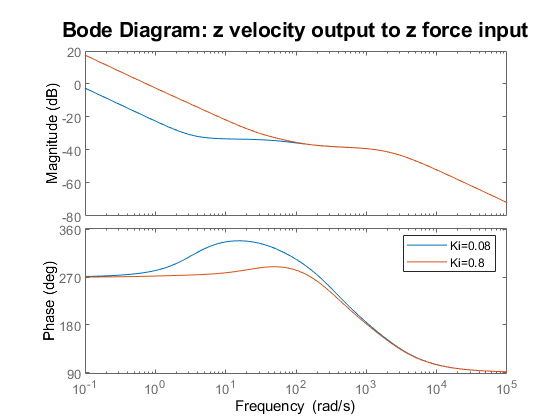

% bode diagram
figure('DefaultAxesFontSize',14)
hold on
bode(dyn_model_ss(2)) % only vz/fz
bode(dyn_model_ss_1(2)) % only vz/fz
legend('Ki=0.08', 'Ki=0.8')
title('Bode Diagram: z velocity output to z force input')

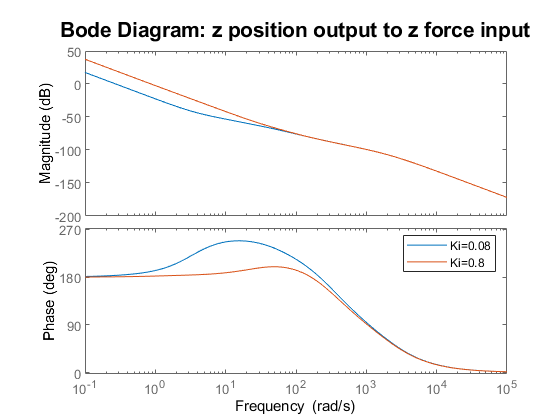

% Bode diagram for the position
s = tf('s');
figure('DefaultAxesFontSize',14)
hold on
bode(tf(dyn_model_ss(2))/s) 
bode(tf(dyn_model_ss_1(2))/s) 
legend('Ki=0.08', 'Ki=0.8')
title('Bode Diagram: z position output to z force input')

### Model without robotic control

% equilibrium values
state0_b = [q0; dq0; ev0];
state0_b'

ans =     1.0293    1.8148   -1.2788         0         0         0         0         0         0


%u0 = double(subs(g, q, q0)); % just compensate gravity effect
u0 = [0;0;0]; % null velocity cmd
in0_b = [u0(2); fe0];
in0_b'

ans =      0     0     0     0


Linearisation at the equilibrium q0

% linearized matrices
Ab0 = double(subs(A_b,[state_b;in_b],[state0_b;in0_b]));
Bb0 = double(subs(B_b,[state_b;in_b],[state0_b;in0_b]));
Cb0 = double(subs(C_b,[state_b;in_b],[state0_b;in0_b]));
Db0 = double(subs(D_b,[state_b;in_b],[state0_b;in0_b]));
% state system
dyn_model_ss_b = ss(Ab0,Bb0,Cb0,Db0);

Validation of the model without the controller by reinjecting the controller and comparing with the complete system:

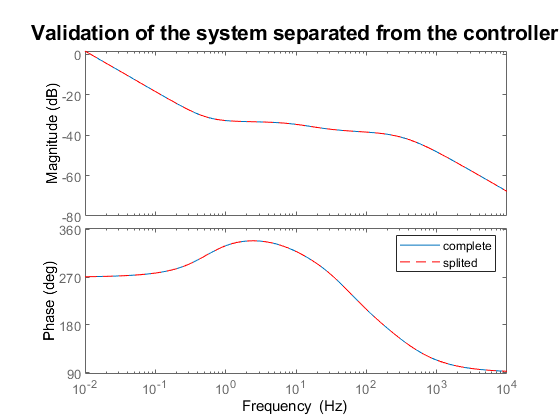

opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
figure('DefaultAxesFontSize',14)
hold on
bodeplot(dyn_model_ss(2), opts)
bodeplot(dyn_model_ss_b(1)*(cz0(1) + cz0(2)/s) + dyn_model_ss_b(3), 'r--', opts)
legend('complete', 'splited')
title('Validation of the system separated from the controller')

Comparative bode diagrams according to the input ($u_z$ or $f_z$)

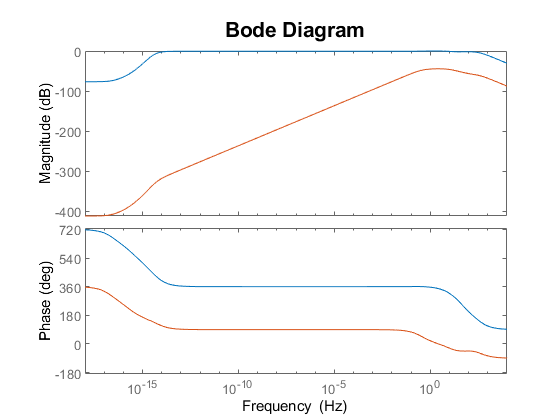

% bode diagram
figure('DefaultAxesFontSize',14)
hold on
bodeplot(dyn_model_ss_b(1), opts) % vz/uz
bodeplot(dyn_model_ss_b(3), opts) % vz/fz (external force on the robot)

### Discrete model without robotic control

% equilibrium values
u_tau0 = double(subs(g,q,q0)); % at equilibrium, only the gravity torque is compensated.
in0_youbot = [u_tau0; fe0(2)];
in0_youbot'

ans =     0.2081    2.2450   -0.0049         0


state0_youBot = [q0;dq0];
state0_youBot'

ans =     1.0293    1.8148   -1.2788         0         0         0


Linearisation at the equilibrium q0, with input command compensating the effect of gravity

% linearized matrices (youBot)
A_youBot0 = double(subs(A_youBot,[state_youBot;in_youBot],[state0_youBot;in0_youbot]));
B_youBot0 = double(subs(B_youBot,[state_youBot;in_youBot],[state0_youBot;in0_youbot]));
C_youBot0 = double(subs(C_youBot,[state_youBot;in_youBot],[state0_youBot;in0_youbot]));
D_youBot0 = double(subs(D_youBot,[state_youBot;in_youBot],[state0_youBot;in0_youbot]));
% youBot continuous state system
dyn_youBot_model_ss = ss(A_youBot0,B_youBot0,C_youBot0,D_youBot0, 'InputName',{'tau(1)','tau(2)','tau(3)','fz'}, 'OutputName', {'dq(1)','dq(2)','dq(3)'});
dyn_youBot_model_tf = minreal(tf(dyn_youBot_model_ss)); % validated with simulink linear analysis

Discretisation:

lin_youBot_tf_sig1_zoh = c2d(dyn_youBot_model_tf(1:3,1:3), dt, 'zoh'); % H = dq/tau_r
lin_youBot_tf_sigf_tustin = c2d(dyn_youBot_model_tf(1:3,4), dt, 'tustin');% H = dq/fz
Cz_d = cz0(1) + z/(z-1)*cz0(2)*dt; % Kp and Ki of the admittance controller
% H = dq/fz
% lin_ctrl_discrete_model = ((eye(3) + z/(z-1)*lin_youBot_tf_sig1_d*Cv_d)*J0)\z/(z-1)*(lin_youBot_tf_sigf_d + lin_youBot_tf_sig1_d*Cv_d*iJ0*[0;1;0]*Cz_d);
% H = dz/fz
% TODO: discretisation is not correct yet.
load youBot_linearisation_alone_tau_fz_inputs_discrete.mat
lin_youBot_tf_sigf_d = minreal(tf(youBot_lin_alone_discrete(1:3, 1))); % dq/fz 
lin_youBot_tf_sig1_d = minreal(tf(youBot_lin_alone_discrete(1:3, 2:4)));
lin_ctrl_discrete_model = minreal((eye(3) + J0*lin_youBot_tf_sig1_d*Cv_d*iJ0)\J0*(lin_youBot_tf_sigf_d + lin_youBot_tf_sig1_d*Cv_d*iJ0*[0;Cz_d;0]));
lin_ctrl_discrete_model_2 = minreal((eye(3) + J0*lin_youBot_tf_sig1_zoh*Cv_d*iJ0)\J0*(lin_youBot_tf_sigf_tustin + lin_youBot_tf_sig1_zoh*Cv_d*iJ0*[0;Cz_d;0]));


$$\dot{\mathit{\mathbf{x}}} \left(z\right)={\mathit{\mathbf{J}}}_0 \frac{z}{z-1}\left(\Sigma_f \left(z\right){\mathit{\mathbf{f}}}_z +\Sigma_1 \left(z\right){\mathit{\mathbf{C}}}_v \left(z\right)\left({\mathit{\mathbf{J}}}_0^{-1} {\left\lbrack 0,{\mathit{\mathbf{C}}}_z \left(z\right){\mathit{\mathbf{f}}}_z ,0\right\rbrack }^t -\dot{q} \right)\right)$$



$$H_d \left(z\right)=\frac{\dot{\mathit{\mathbf{x}}} \left(z\right)}{f_z \left(z\right)}={\left(I+{\mathit{\mathbf{J}}}_0 \Sigma_1 \left(z\right){\mathit{\mathbf{C}}}_v \left(z\right){\mathit{\mathbf{J}}}_0^{-1} \;\right)}^{-1} J_0 \left(\Sigma_f \left(z\right)+\Sigma_1 \left(z\right){\mathit{\mathbf{C}}}_v \left(z\right){\mathit{\mathbf{J}}}_0^{-1} {\left\lbrack 0,1,0\right\rbrack }^t {\mathit{\mathbf{C}}}_z \left(z\right)\right)$$


Validation is done in comparison with the simulink simulation in the next section.

## Comparison with simulink simulation

%load linsys_no_secondary_ctrl_2020.mat
%load linsys_no_secondary_ctrl_2020b.mat %erroneous integral gain on
%velocity
%ss_simulink = minreal(linsys1(2));
load linsys_no_secondary_ctrl_2021c.mat
ss_simulink = minreal(simulink_linear_continuous_state_sys(2));

6 states removed.


%load linsys_no_secondary_ctrl_discrete_int_2021.mat %erroneous integral
%gain on velocity
load linsys_no_secondary_ctrl_discrete_int_2021b.mat
ss_discrete_simulink = minreal(simulink_linear_discrete_state_sys(2));

3 states removed.


%load linear_tf_analytical_approach.mat % previous analytical approach
ss_analytic = minreal(dyn_model_ss(2));

5 states removed.


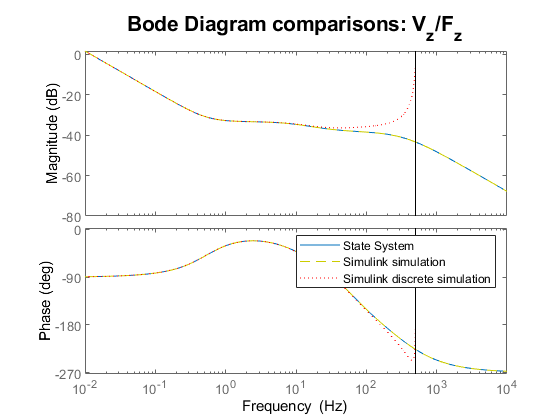

%tf_analytic = -minreal(Hz_youBot);
opts = bodeoptions('cstprefs');
opts.PhaseMatching = 'on';
opts.FreqUnits = 'Hz';
figure('DefaultAxesFontSize',14)
hold on
bodeplot(ss_analytic, opts) 
bodeplot(ss_simulink, 'y--', opts)
bodeplot(ss_discrete_simulink, 'r:', opts)
legend('State System', 'Simulink simulation', 'Simulink discrete simulation')
title('Bode Diagram comparisons: V_z/F_z')

% 
figure('DefaultAxesFontSize',14)
hold on
bodeplot(minreal(ss_analytic*s), opts) 

3 states removed.


bodeplot(minreal(ss_simulink*s),'y--', opts)

3 states removed.


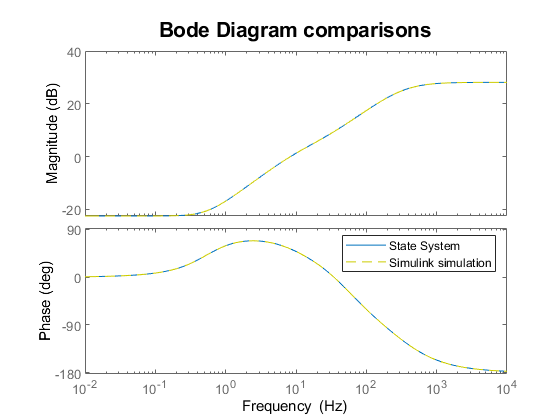

legend('State System', 'Simulink simulation')
title('Bode Diagram comparisons')

% DC gain comparison
DC_gain = dcgain(minreal(ss_analytic*s))

3 states removed.


DC_gain = 0.0750

Validation of the discrete model computed in the previous section

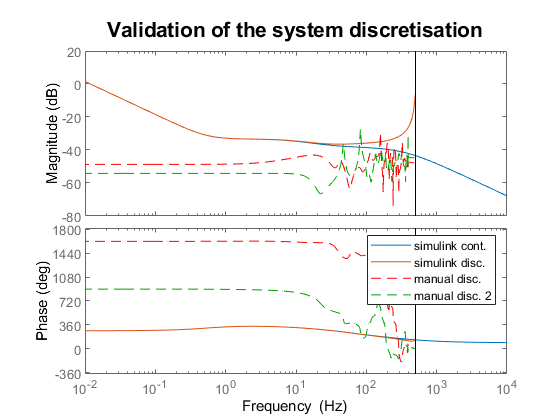

opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
figure('DefaultAxesFontSize',14)
hold on
bodeplot(ss_simulink, opts)
bodeplot(ss_discrete_simulink, opts)
bodeplot(lin_ctrl_discrete_model(2), 'r--', opts)
bodeplot(lin_ctrl_discrete_model_2(2), 'g--', opts)
legend('simulink cont.', 'simulink disc.', 'manual disc.', 'manual disc. 2')
title('Validation of the system discretisation')

## Analyse

### Apparent dynamics

The apparent mass of the system can be deduced from the magnitude of the Bode diagram around the studied frequency. *This section need to be elaborated...*

freq_study = 0.9; % 0.9Hz
[mag,~,~] = bode(minreal(ss_analytic*s), 2*pi*freq_study);

3 states removed.


M_app = 1/mag;

This apparent mass is to compare with the actual apparent mass of the system when it is not controled.

load linsys_youBot_2021b.mat
ss_simulink_youBot = simulink_linear_continuous_state_sys(2);
[mag,phase,wn] = bode(minreal(ss_simulink_youBot*s), 2*pi*freq_study);

2 states removed.


M_app_yB = 1/mag;
%
opts.PhaseMatching = 'off';
opts.PhaseWrapping = 'on';
figure('DefaultAxesFontSize',14)
hold on
bodeplot(minreal(ss_analytic/s), opts) 
bodeplot(minreal(ss_simulink_youBot/s), opts)

1 state removed.


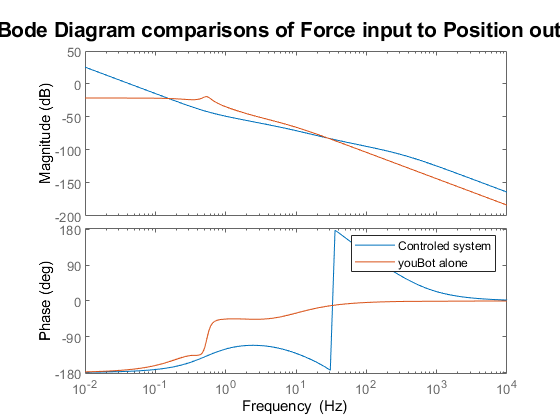

legend('Controled system', 'youBot alone')
title('Bode Diagram comparisons of Force input to Position output')

### Stability analysis

#### Parametric analysis of the system coupled with an impedance environment

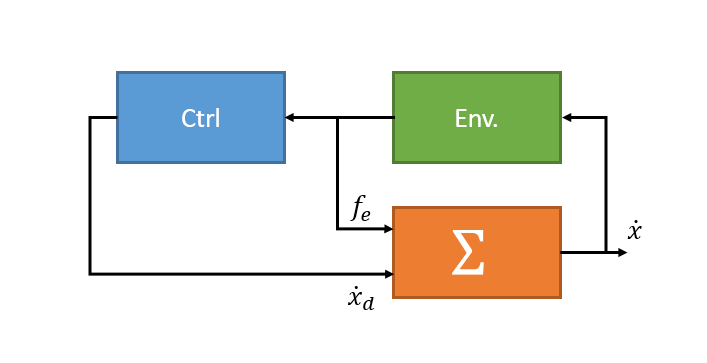

If we consider the robot ($\Sigma$) with the cartesian admittance controller (Ctrl) used by Fortineau (2020), an impedance environment (second order system) can be coupled to close the control loop, an analysis can then be done with varying stiffness ($K$) and damping ($B$) of the environment.

% cartesian admittance controller
% Ctrl = double(subs(Kp, cz, cz0)) + double(subs(Ki, cz, cz0))/s; % 3D to 3D
Ctrl = cz0(1) + cz0(2)/s; % 1D to 1D (fz to vz)

The environnement impedance is defined with K the stiffness, B the damping and M the mass and also a second order filter to represent the pass band of the human arm:


$$\frac{F_e \left(s\right)}{V_e \left(s\right)}=\mu \;\left(s\right)=-\left(\frac{K}{s}+B+Ms\right)\frac{1}{{\left(1+\tau_m s\right)}^2 }$$
 

The multi-input model of the robot can be splited betwen the part that takes the controller cartesian velocity setpoint and the part that takes the force input. In this case, only the velocity setpoint along the z axis is considered, and the robot system (with joint velocity control) is splited into 2 subsystems $\Sigma_1$that takes the controller output as input and $\Sigma_f$ that takes the interaction force as input. The 2 subsystems are then summed to get the cartesian velocity $v_e$ as output:

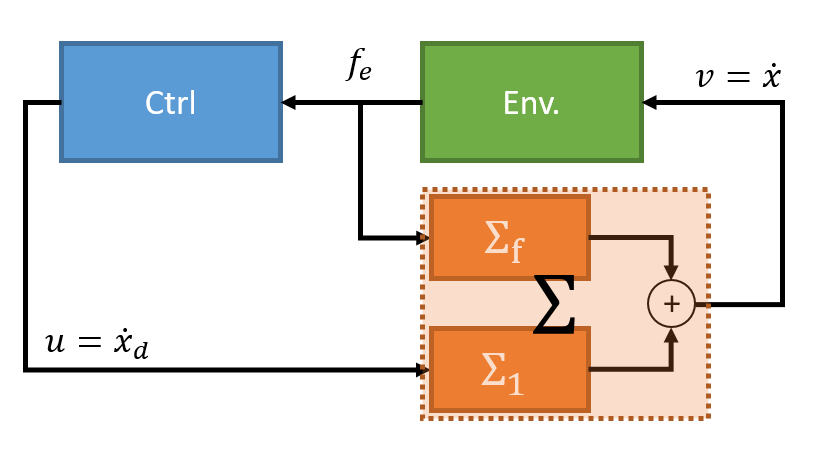


$$u\left(s\right)=C\left(s\right)F_e \left(s\right)=C\left(s\right)\mu \left(s\right)V_e \left(s\right)=C\left(s\right)\mu \left(s\right)\left(\Sigma_1 \left(s\right)u\left(s\right)+\Sigma_f \left(s\right)F_e \left(s\right)\right)$$



$$\left(I-C\left(s\right)\mu \left(s\right)\Sigma_1 \left(s\right)\right)u\left(s\right)=C\left(s\right)\mu \left(s\right)\Sigma_f \left(s\right)F_e \left(s\right)$$



$$u\left(s\right)={\left(I-C\left(s\right)\mu \left(s\right)\Sigma_1 \left(s\right)\right)}^{-1} C\left(s\right)\mu \left(s\right)\Sigma_f \left(s\right){\;F}_e \left(s\right)$$


Considering the force reference:


$$\frac{\dot{x} }{f_{\textrm{ref}} }={\left({-\Sigma }_f \left(s\right)\mu \left(s\right)-\Sigma_1 \left(s\right)C\left(s\right)\mu \left(s\right)+I\right)}^{-1} \Sigma_1 \left(s\right)C\left(s\right)$$


% environment
% Env = K + B*s + M*s^2;
K_range = -11:10:20000;
B_range = -1.5:0.5:100;
tau_m = 16e-3;
if 0
    M = 0.5*eye(3);
    answer = questdlg('Do you want to execute the parametric analysis ? This might takes more than a minute.', ...
    	'Warning conclusion section', 'Yes','No','No');
    if strcmp("Yes", answer)
        waitB = waitbar(0,'1','Name','2D parametric analysis',...
            'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
        setappdata(waitB,'canceling',0);
        lK = length(K_range); lB = length(B_range);
        criterion = [];
        criterion(lK, lB) = 0;
        for iK = 1:lK
            K = K_range(iK)*eye(3);
            for iB = 1:lB
                if mod(iB,1e3) == 1 % otherwise slows down the computation
                    if getappdata(waitB,'canceling')
                        break
                    end
                    waitbar(((iK-1)*lB + iB)/(lK*lB), waitB, ...
                        sprintf('%.2f%%', ((iK-1)*lB + iB)/(lK*lB)*100));
                end
                B = B_range(iB)*eye(3);
                Env = (K/s + B + M*s)/(1+tau_m*s)^2;
                %TFcl = (1 - Ctrl*Env(2,2)*tf(dyn_model_ss_b(1)))\(Ctrl*Env(2,2)*tf(dyn_model_ss_b(3))); % Vd/Fe
                TFcl = feedback(dyn_model_ss(2),-(-Env));
                criterion(iK,iB) = max(real(pole(TFcl)));
            end
        end
        delete(waitB)
    end
else
    K_test = 200;
    K_test_2 = 4e3
    B_test = 12.5;
    M_test = 0.5;
    mu = -(K_test + B_test*s + M_test*s^2)/s*1/(1+tau_m*s)^2;
    mu2 = -(K_test_2 + B_test*s + M_test*s^2)/s*1/(1+tau_m*s)^2;
    % V/f_ref (only alongt the z axis)
    % Continuous
    sigma_1 = tf(dyn_model_ss_b(1));
    sigma_f = tf(dyn_model_ss_b(3));
%     H_test = minreal((-sigma_f*mu - sigma_1*Ctrl*mu + 1)\(sigma_1*Ctrl));
    figure
    bode(minreal(-mu*dyn_model_ss(2)), minreal(-mu2*dyn_model_ss(2)))
    figure
    nyquist(-mu*dyn_model_ss(2))
    H_test = minreal(feedback(dyn_model_ss(2), -mu));
    H_test_sep = minreal((1 - mu*(sigma_f+sigma_1*Ctrl))\(sigma_f+sigma_1*Ctrl));
    %H2_test = minreal();
    max(real(pole(H_test)))
    damp(H_test)
    figure
    step(H_test)
    % Discrete
    %ss_discrete_simulink
    Kp_range = 0:1e-3:5e-2;
    Ki_range = 0:1e-2:1;
    for Kp_i = 1:length(Kp_range)
        for Ki_i = 1:length(Ki_range)
            Ctrl_i = Kp_range(Kp_i) + Ki_range(Ki_i)/s;
            Hi = minreal((1 - mu*(sigma_f+sigma_1*Ctrl_i))\(sigma_f+sigma_1*Ctrl_i));
            criterion_ctrl(Kp_i,Ki_i) = max(real(pole(Hi)));
            is_stable_ctrl(Kp_i,Ki_i) = isstable(Hi);
        end
    end
end

ans = 450.3589

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.93e+00 + 6.97e-05i     1.00e+00       1.93e+00         5.18e-01    
 -1.93e+00 - 6.97e-05i     1.00e+00       1.93e+00         5.18e-01    
 -1.95e+00                 1.00e+00       1.95e+00         5.13e-01    
 -2.40e+00                 1.00e+00       2.40e+00         4.16e-01    
 -2.40e+00                 1.00e+00       2.40e+00         4.16e-01    
 -2.83e+00                 1.00e+00       2.83e+00         3.53e-01    
 -2.70e+00 + 2.95e+00i     6.75e-01       4.00e+00         3.70e-01    
 -2.70e+00 - 2.95e+00i     6.75e-01       4.00e+00         3.70e-01    
 -4.97e+00 + 1.36e-05i     1.00e+00       4.97e+00         2.01e-01    
 -4.97e+00 - 1.36e-05i     1.00e+00       4.97e+00         2.01e

## Conclusion

The linear analysis done here brings the same results as the simulink linear analysis. The previous linear analysis that was attempted without state representation, and with a simplified assumption for the linearisation of the control (inverse jacobian notably) gives some deviation with a globaly equivalent behaviour. The differences might be explained by the approximation of the assumption. For the rest of the analysis, the current linerisation done here will bne kept.

% Variation of Ki
answer = questdlg('Do you want to execute the conclusion section ? This might takes few minutes.', ...
	'Warning conclusion section', 'Yes','No','No');
if strcmp("Yes", answer)
    Kiz = 1e-3*(8:5:1000);
    Kpz = 0.015*ones(size(Kiz));
    DC_gains = zeros(size(Kiz));
    cz0i = [Kpz;Kiz];
    h = waitbar(0,'Initializing waitbar...');
    % linearized matrices
    Ai1 = subs(A,[state;in],[state0;in0]);
    Bi1 = subs(B,[state;in],[state0;in0]);
    Ci1 = subs(C,[state;in],[state0;in0]);
    Di1 = subs(D,[state;in],[state0;in0]);
    for ii = 1:length(Kiz)
        Ai = double(subs(Ai1,cz,cz0i(:,ii)));
        Bi = double(subs(Bi1,cz,cz0i(:,ii)));
        Ci = double(subs(Ci1,cz,cz0i(:,ii)));
        Di = double(subs(Di1,cz,cz0i(:,ii)));
        % state system
        dyn_model_ss_i = ss(Ai,Bi,Ci,Di);
        DC_gains(ii) = dcgain(minreal(dyn_model_ss_i(2)*s, [], false)); % false delete verbose from minreal func
        waitbar(ii/1000,h,sprintf('%.1f%%...',0.1*ii))
    end 
    close(h)
    figure('DefaultAxesFontSize',14)
    hold on
    plot(Kiz,1./DC_gains)
    plot(Kiz(16),1./DC_gains(16), 'p')
    xlabel('Ki')
    ylabel('Mass (kg)')
    title('Apparent mass against Ki gain')
end

Last update 29/10/2021, Vincent FORTINEAU, PhD. student at L2S, Université Paris-Saclay, France